data=load('C:\Users\amitp25\Downloads\mldl_course_files\FashionImageProject\fashionMNIST.mat')

data = struct with fields:
     xTest: [28×28×10000 uint8]
    xTrain: [28×28×60000 uint8]
     yTest: [10000×1 categorical]
    yTrain: [60000×1 categorical]


data

data = struct with fields:
     xTest: [28×28×10000 uint8]
    xTrain: [28×28×60000 uint8]
     yTest: [10000×1 categorical]
    yTrain: [60000×1 categorical]


X_train=reshape(data.xTrain,28,28,1,numel(yTrain));
Y_train=data.yTrain;
X_test=reshape(data.xTest,28,28,1,numel(yTest));
Y_test=data.yTest;

CNN Network Architecture

layers=[...
    imageInputLayer([28,28,1])
    convolution2dLayer(3,8,"padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"Stride",2)
    convolution2dLayer(2,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"stride",2)
    convolution2dLayer(2,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options=trainingOptions("adam", ...
    "MiniBatchSize",256,"Plots","training-progress", ...
    "MaxEpochs",100,"Verbose",true, ...
    "ValidationData",{X_test,Y_test},"InitialLearnRate",0.01)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 100
                   MiniBatchSize: 256
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[28×28×1×10000 uint8]  [10000×1 categorical]}
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      Worker

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       15.23% |       39.94% |       2.6735 |       1.9064 |          0.0100 |
|       1 |          50 |       00:00:16 |       82.03% |       82.89% |       0.5060 |       0.4726 |          0.0100 |
|       1 |         100 |       00:00:27 |       85.94% |       86.97% |       0.3483 |       0.3700 |          0.0100 |
|       1 |         150 |       00:00:39 |       86.72% |       86.20% |       0.3341 |   

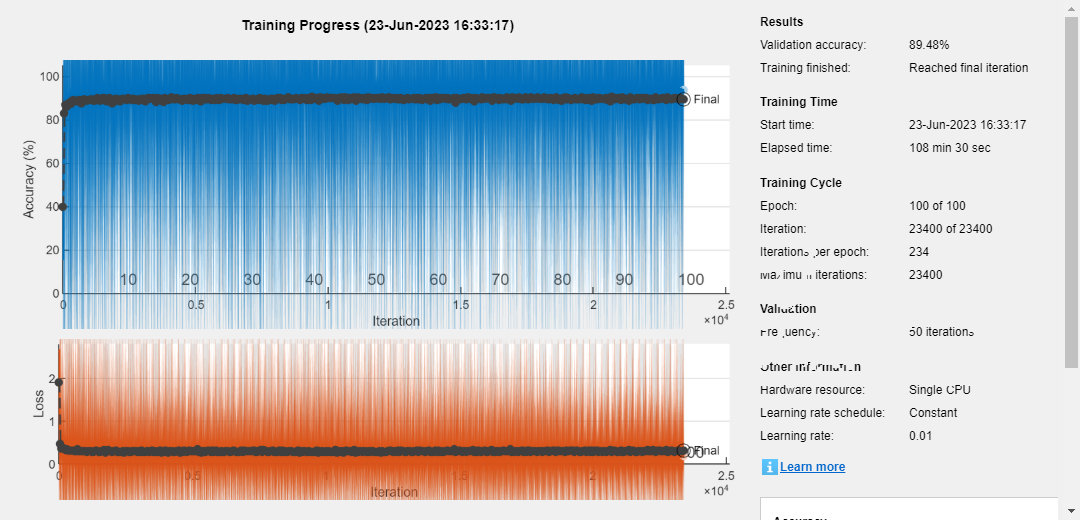

cnn_net =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


cnn_net=trainNetwork(X_train,Y_train,layers,options)

pred=classify(cnn_net,X_test)

pred = 10000×1 categorical array
     Ankle Boot 
     Pullover 
     Trouser 
     Trouser 
     T-Shirt 
     Trouser 
     Coat 
     Shirt 
     Sandal 
     Sneaker 
     Coat 
     Sandal 
     Sandal 
     Dress 
     Coat 
     Trouser 
     Pullover 
     Coat 
     Bag 
     T-Shirt 
     Pullover 
     Sandal 
     Sneaker 
     Ankle Boot 
     Trouser 
     Pullover 
     Shirt 
     T-Shirt 
     Ankle Boot 
     Dress 


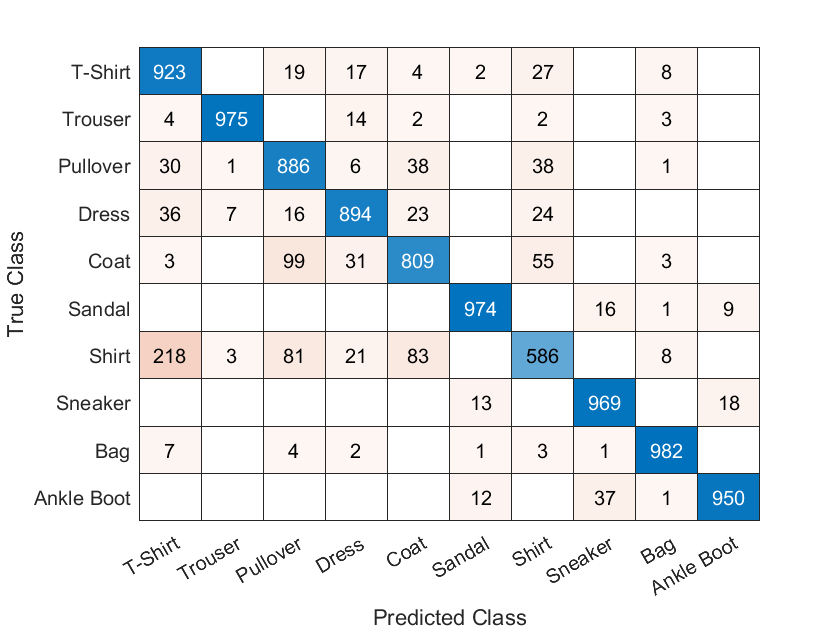

confusionchart(Y_test,pred)